# Create Surface Plot

Create three matrices of the same size. Then plot them as a surface. The surface plot uses `Z` for both height and color.

[X,Y] = meshgrid(-5:.1:5);
Z = 0.5*Y.*sin(X) - 0.5*X.*cos(Y);
% CO(:,:,1) = Z*2; % red
% CO(:,:,2) = Z*15; % green
% CO(:,:,3) = Z*10; % blue
s = surf(X,Y,Z);
cmap = colormap;
cmin = min(s.CData(:));
cmax = max(s.CData(:));
m = length(cmap);
index = fix((s.CData-cmin)/(cmax-cmin)*(m-1))+1; %A
RGB = ind2rgb(index,cmap);

*Copyright 2024 The MathWorks, Inc.*

# Save Surface as a GL Transmission Format (glTF) file

This section uses GLTF for MATLAB

[Version 1.22](https://www.mathworks.com/matlabcentral/fileexchange/123955-gltf-for-matlab#version_history_tab) (931 KB) by [Rohan Chabukswar](https://www.mathworks.com/matlabcentral/profile/authors/5473992)

to create the glTF file.

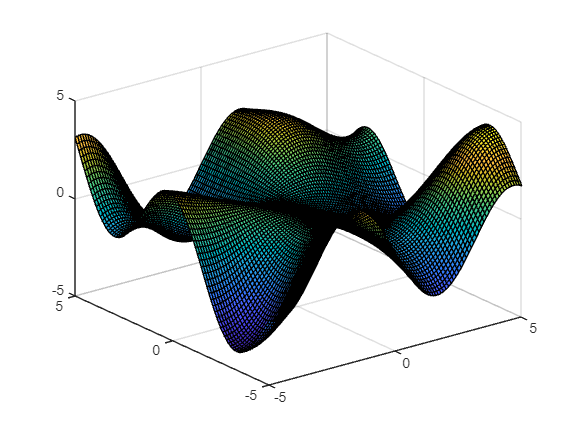

% Get the faces, vertices, and the corresponding colours.
% Use triangles as GLTF only supports triangular faces.
[F,V,C]=surf2patch(X,Y,Z,RGB,'triangles');
% Get the rectangular faces that MATLAB would use. We will use these to
% create edges.
[E,~]=surf2patch(X,Y,Z);
% Create the list of edges. For example, for Face 1 2 3 4, edges are 1-2,
% 2-3, 3-4, and 4-1.
E=reshape(E(:,[1 2 2 3 3 4 4 1])',2,[])';
% Since the direction of the edge doesn't matter, we sort it so the
% lower-indexed vertex is first.
E=sort(E,2); %#ok<UDIM>
% This enables us to discard duplicate edges.
E=unique(E,'rows');
% Scale vertices based on data aspect ratio and plot aspect ratio to make
% the 3D Object look as much like the MATLAB plot as possible.
V=V./daspect.*pbaspect;
% Rotate the vertices since we are more used to Z-axis being "up" and
% Y-axis being "back".
V=V*[0 0 1;1 0 0;0 1 0];

% Create the GLTF object.
gltf=GLTF();
% Add a white material which will act as the "base coat" over which the
% vertex colours will be painted. There is no real need to do this, except
% that we want the material to be visible from both sides.
white_idx=gltf.addMaterial('baseColorFactor',ones(1,3),'doubleSided',true);
% Add a mesh with the vertices, faces, and colours. Use the white material.
mesh_idx=gltf.addMesh(V,'indices',F,'COLOR',C,'material',white_idx);
% Get the edge colour.
CE=s.EdgeColor;
% Add the material which we will use to display edges.
edge_colour_idx=gltf.addMaterial('baseColorFactor',CE);
% Add a second primitive to the same mesh with vertices and edges. Use mode
% "LINES" and the edge colour material.
gltf.addPrimitiveToMesh(mesh_idx,V,'indices',E,'mode',"LINES",'material',edge_colour_idx);
% Instantiate the mesh in a node.
gltf.addNode('mesh',mesh_idx);
% Add axes as seen in the figure.
gltf=addAxes(gltf,'baseRotation',[0 0 1;1 0 0;0 1 0],'axisIds',["x00";"0y0";"01z"],'gridIds',["xy0","x1z","1yz"],'backPlanes',["xy0","x1z","1yz"],'scaleFactor',7.5,'axis',s.Parent,'fontFile',"arial.svg",'plotAspect',true,'dataAspect',true);

% Write the GLTF file.
gltf.writeGLTF("surf10.gltf");